# Sequence-to-Sequence Classification Using Deep Learning

This example shows how to classify each time step of sequence data using a long short-term memory (LSTM) network.

To train a deep neural network to classify each time step of sequence data, you can use a *sequence-to-sequence LSTM network*. A sequence-to-sequence LSTM network enables you to make different predictions for each individual time step of the sequence data.

The example trains an LSTM network to recognize the phase of a power profile given time series data representing power demand in dc bus. The training data contains time series data for three flights. Each sequence has one feature and varies in length. The data set contains 3 training observations and one test observation.

## Load Sequence Data

The feature correspond to the power profile requirement.

load load_to_train
XTrain

XTrain = 1×50 cell array
    {1×951 double}    {1×1040 double}    {1×1048 double}    {1×943 double}    {1×1035 double}    {1×1049 double}    {1×1053 double}    {1×1030 double}    {1×935 double}    {1×1031 double}    {1×1032 double}    {1×1046 double}    {1×928 double}    {1×938 double}    {1×936 double}    {1×945 double}    {1×1032 double}    {1×1027 double}    {1×941 double}    {1×1052 double}    {1×1048 double}    {1×1042 double}    {1×1038 double}    {1×1038 double}    {1×925 double}    {1×1030 double}    {1×1050 double}    {1×1032 double}    {1×1040 double}    {1×927 double}    {1×934 double}    {1×930 double}    {1×1044 double}    {1×945 double}    {1×923 double}    {1×948 double}    {1×924 double}    {1×955 double}    {1×930 double}    {1×1057 double}    {1×946 double}    {1×1046 double}    {1×942 double}    {1×1051 double}    {1×930 double}    {1×1043 double}    {1×927 double}    {1×1046 double}    {1×942 double}    {1×943 double}


Visualize one training sequence in a plot. Plot the first feature of the first training sequence and color the plot according to the corresponding activity.

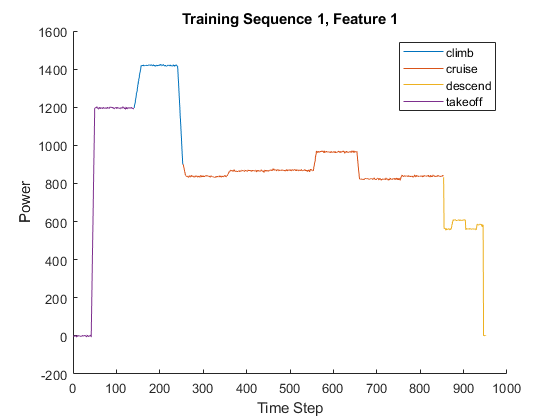

X = XTrain{1}(1,:);
classes = categories(YTrain{1});

figure
for j = 1:numel(classes)
    label = classes(j);
    idx = find(YTrain{1} == label);
    hold on
    plot(idx,X(idx))
end
hold off

xlabel("Time Step")
ylabel("Power")
title("Training Sequence 1, Feature 1")
legend(classes,'Location','northeast')

## Define LSTM Network Architecture

Define the LSTM network architecture. Specify the input to be sequences of size 3 (the number of features of the input data). Specify an LSTM layer with 200 hidden units, and output the full sequence. Finally, specify five classes by including a fully connected layer of size 5, followed by a softmax layer and a classification layer.

numFeatures = 1;
numHiddenUnits = 200;
numClasses = 4;

layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits,'OutputMode','sequence')
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

Specify the training options. Set the solver to `'adam'`. Train for 60 epochs. To prevent the gradients from exploding, set the gradient threshold to 2.

options = trainingOptions('adam', ...
    'MaxEpochs',120, ...
    'GradientThreshold',2, ...
    'Verbose',0, ...
    'Plots','training-progress', 'MiniBatchSize',2);

Train the LSTM network with the specified training options using `trainNetwork`. Each mini-batch contains the whole training set, so the plot is updated once per epoch. The sequences are long, so it might take some time to process each mini-batch and update the plot.

net = trainNetwork(XTrain,YTrain,layers,options);
% save('net_to_test','net');

## Test LSTM Network

Load the test data and classify the activity at each time step.

Load the human activity test data. `XTest` contains a single sequence of dimension 3. `YTest` is contains sequence of categorical labels corresponding to the activity at each time step.

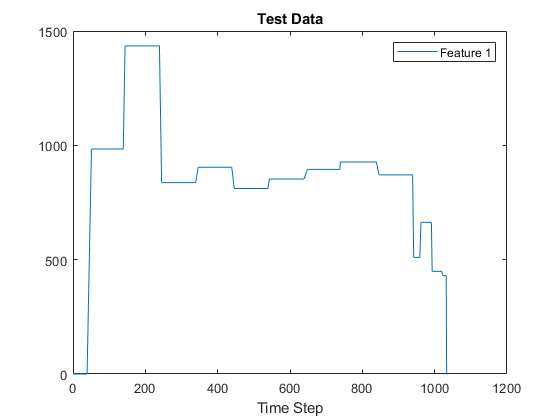

load load_to_test
load net_to_test
figure
plot(XTest{1}')
xlabel("Time Step")
legend("Feature " + (1:1))
title("Test Data")

Classify the test data using `classify`. 

YPred = classify(net,XTest{1});

Usually, it is faster to make predictions on full sequences when compared to making predictions one time step at a time. 

Calculate the accuracy of the predictions.

acc = sum(YPred == YTest{1})./numel(YTest{1})

acc = 0.9913

Compare the predictions with the test data by using a plot.

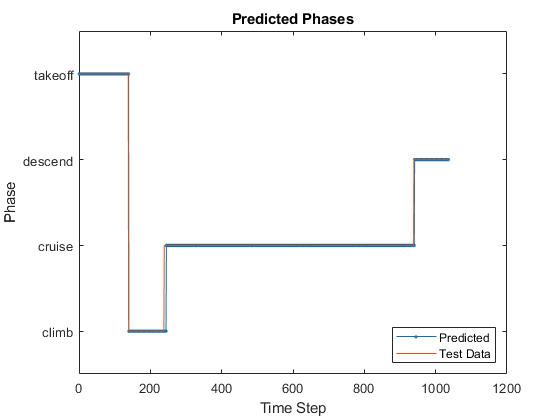

figure
plot(YPred,'.-')
hold on
plot(YTest{1})
% testedknn=trainedModel.predictFcn(to_try);
% ttt = [];
% for i=1:height(testedknn)
%     ttt = [ttt categorical(convertCharsToStrings(testedknn{i}))];
% end
% acc2 = sum(ttt == YTest{1})./numel(YTest{1})
% plot(ttt)
hold off

xlabel("Time Step")
ylabel("Phase")
title("Predicted Phases")
legend(["Predicted" "Test Data" "Test with NN"],'Location','southeast')

*Based on LSTM network classification - Copyright 2018 The MathWorks, Inc.*

# Train Shallow NN

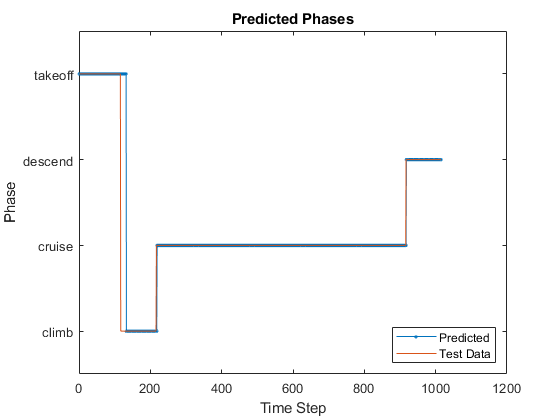

load load_to_train
netNN = feedforwardnet(40);
[netNN,tr] = train(netNN,str2double(to_classify.power)',...
    str2double(to_classify.legend_number)');

# Test Shallow NN

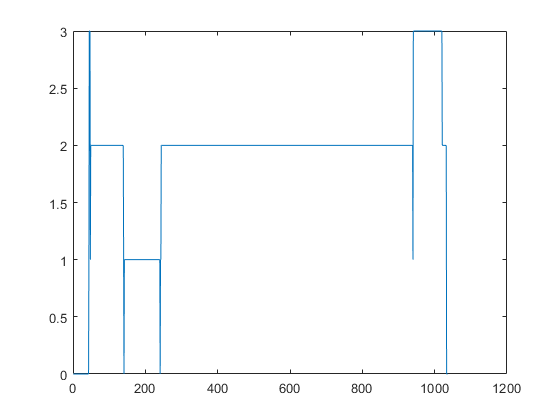

load load_to_test
res = round(netNN(str2double(to_try.power)'),0);
cat_snn = [];
for i=1:length(res)
    if res(i) == 0
        j = "takeoff";
    elseif res(i) == 1
        j = "climb";
    elseif res(i) == 2
        j = "cruise";
    else 
        j = "descend";
    end
    cat_snn = [cat_snn categorical(j)];
end
clf
plot(1:length(str2double(to_try.power)'),res)

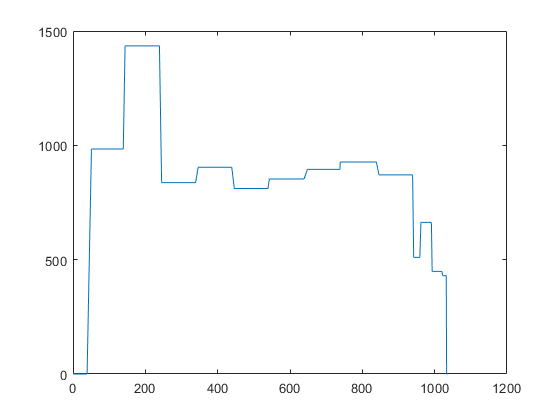

figure
plot(1:length(str2double(to_try.power)'),str2double(to_try.power)')

acc = sum(res == str2double(to_try.legend_number)')./numel(str2double(to_try.power)')

acc = 0.8842

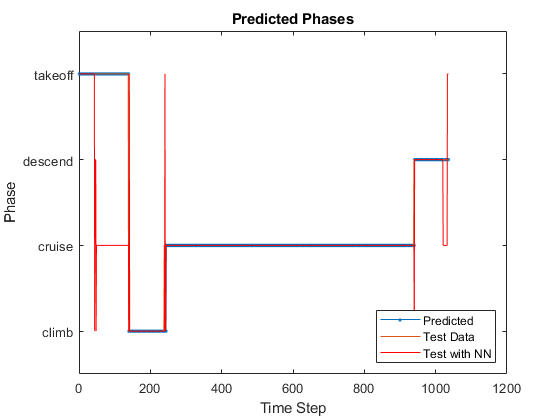


figure
plot(YPred,'.-')
hold on
plot(YTest{1})
plot(cat_snn,'r')
hold off
xlabel("Time Step")
ylabel("Phase")
title("Predicted Phases")
legend(["Predicted" "Test Data" "Test with NN"],'Location','southeast')